## **1a. Let Load and normalize data**

close all;
clear;


 load('LoaderA14-04-01'); 

## Convert data to matrix

April_data = dataTT{:,:};

## Extract channel names and time vector

timeVec = dataTT.Properties.RowTimes;
channelNames = dataTT.Properties.VariableNames;

## Visualize data

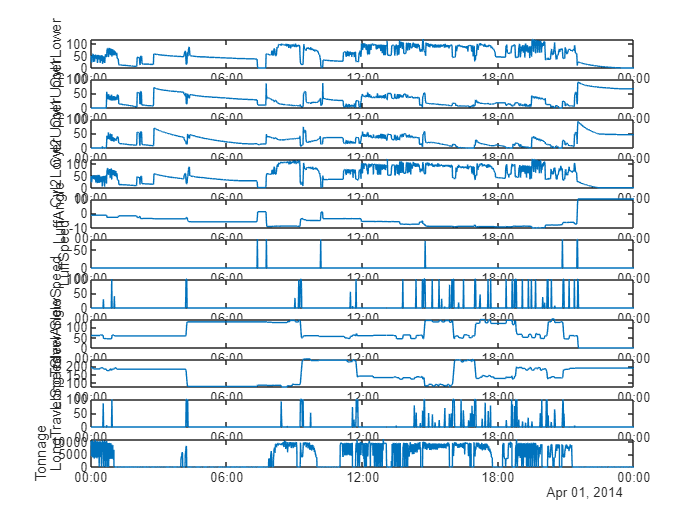

nrChannels = size(April_data, 2);
figure
for i = 1:nrChannels
    subplot(11,1,i)
    plot(timeVec, April_data(:,i));
    ylabel(channelNames{i});
end

## Remove NaNs from data

rowsWithNans = sum(isnan(April_data),2);
April_data(rowsWithNans>0, :) = [];

## Perform PCA

First step: normalize data

stdData = std(April_data);

Replace all zero standard deviations with a 1, so that we can avoid problems with division by 0.

stdData(stdData==0) = 1;
April_data  = (April_data  - mean(April_data))./stdData;

[U, V, S] = pca(April_data);

## Calculate variance kept by the first 3 principal components

variance_kept = cumsum(S)./sum(S);
first_three_variance = variance_kept(1:3)

first_three_variance =     0.3820
    0.5293
    0.6742


##  Plot variance explained

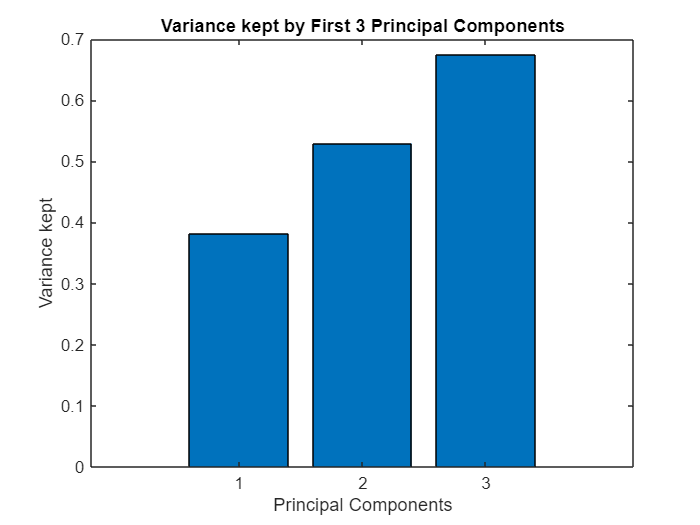

figure;
bar(first_three_variance);
title('Variance kept by First 3 Principal Components');
xlabel('Principal Components');
ylabel('Variance kept');

## 1b. Identify day with highest variance

The day with the highest variation is determined after the variance for each day has been calculated. High variance suggests that there is a lot of fluctuation in the data today, which could signal an abnormality or an interesting event.

[~, max_day] = max(first_three_variance);
disp(['Day with highest variance: ', num2str(max_day)]);

Day with highest variance: 3


## 1c. Plot the data for the identified day

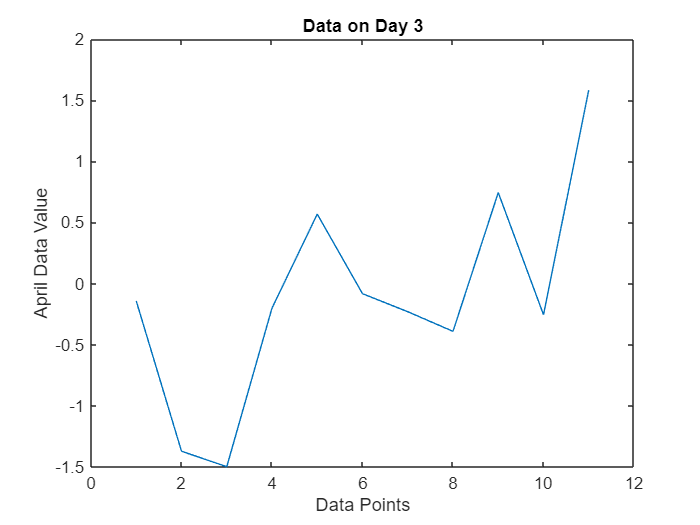

figure;
plot(April_data(max_day, :));
title(['Data on Day ', num2str(max_day)]);
xlabel('Data Points');
ylabel('April Data Value');

## 1d. Let Explore other PCA analyses on the other data from April

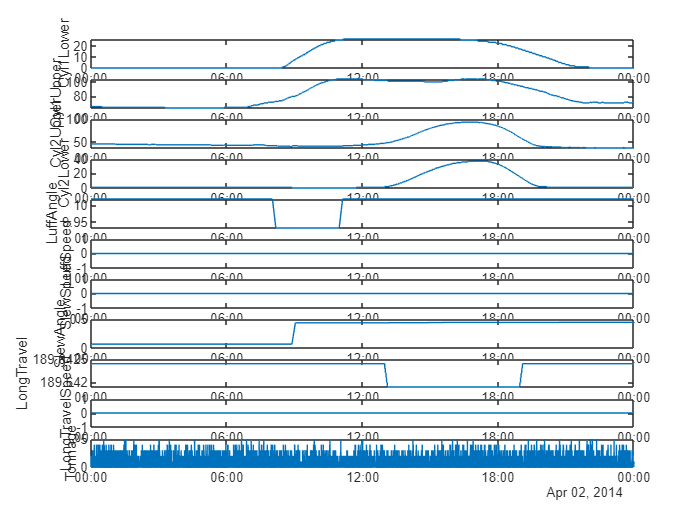

% Let Load and normalize data
load('LoaderA14-04-02'); 

% Convert data to matrix
April_data2 = dataTT{:,:};

% Extract channel names and time vector
timeVec = dataTT.Properties.RowTimes;
channelNames = dataTT.Properties.VariableNames;

% Visualize data
nrChannels = size(April_data2, 2);
figure
for i = 1:nrChannels
    subplot(11,1,i)
    plot(timeVec, April_data2(:,i));
    ylabel(channelNames{i});
end


% Remove NaNs from data
rowsWithNans = sum(isnan(April_data2),2);
April_data2(rowsWithNans>0, :) = [];

% First step: normalize data
stdData = std(April_data);

% Replace all zero standard deviations with a 1, so that we can avoid problems with division by 0.
stdData(stdData==0) = 1;
April_data2  = (April_data2  - mean(April_data2))./stdData;

% Perform PCA
[C, K, L] = pca(April_data2);

% Calculate variance kept by the first 3 principal components
variance_kept2 = cumsum(L)./sum(L);
first_three_variance2 = variance_kept2(1:3)

first_three_variance2 =     0.7993
    0.9920
    0.9986


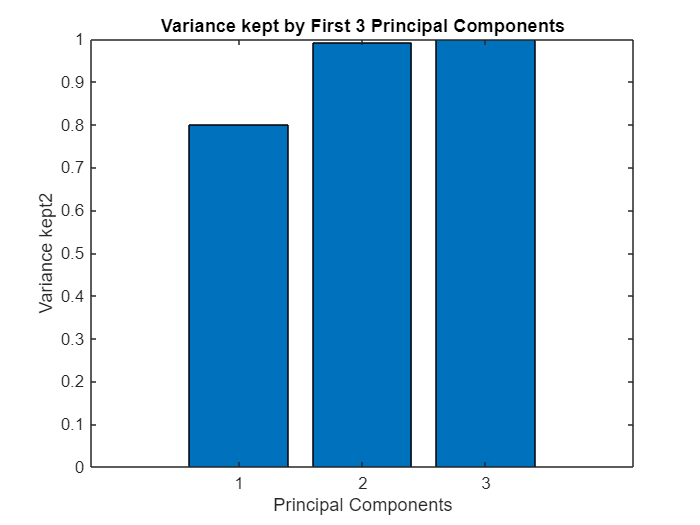


%  Plot variance explained

figure;
bar(first_three_variance2);
title('Variance kept by First 3 Principal Components');
xlabel('Principal Components');
ylabel('Variance kept2');


%  Identify day with highest variance
[~, max_day2] = max(first_three_variance2);
disp(['Day with highest variance: ', num2str(max_day2)]);

Day with highest variance: 3


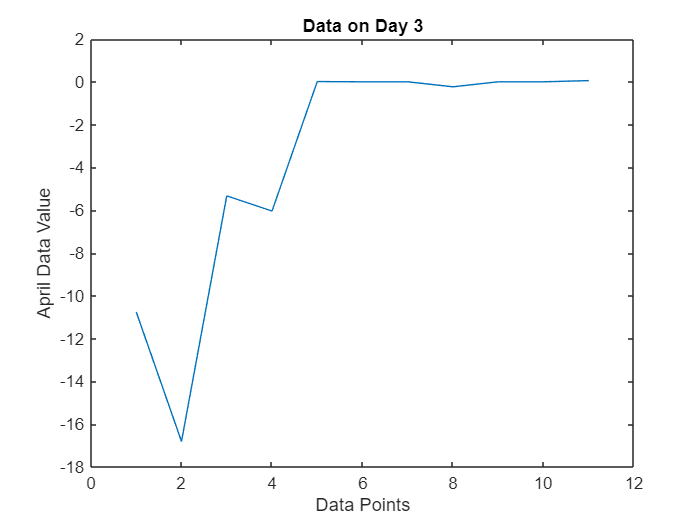


% Plot the data for the identified day
figure;
plot(April_data2(max_day2, :));
title(['Data on Day ', num2str(max_day2)]);
xlabel('Data Points');
ylabel('April Data Value');